# **Visualize the Phase Plane for the Ramsey-Cass-Koopmans Model**

This example shows how to visualize the 2D phase plane corresponding to the system of ODEs defined by the Ramsey-Cass-Koopmans model.

*Copyright 2016-2023 The MathWorks, Inc.*

## Define the model parameters.

See [`defineRCKParams`](matlab: edit defineRCKParams) for more details.

defineRCKParams

## Visualize the phase portrait.

figure
h = streamslice(params.K, params.C, params.dK, params.dC, 2, "noarrows", "cubic");
set(h, "LineStyle", ":", "LineWidth", 1.5)

Hide all but one streamslice from the legend.

set(h(2:end), "HandleVisibility", "off")

Plot the steady-state vertical line and smooth curve.

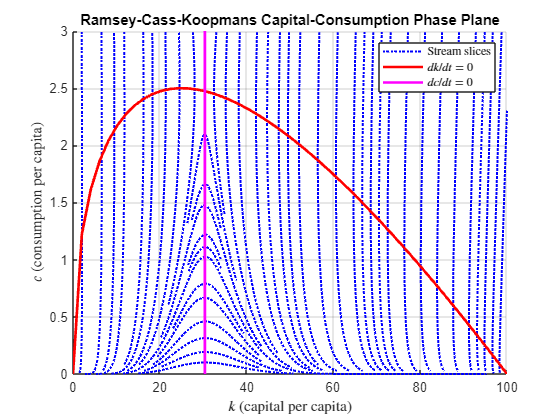

hold on
plot(params.k_fine, params.c_star, "r", "LineWidth", 2)
plot([params.k_steady, params.k_steady], ylim(), "m", "LineWidth", 2)
xlabel("$k$ (capital per capita)", "Interpreter", "latex")
ylabel("$c$ (consumption per capita)", "Interpreter", "latex")
title("Ramsey-Cass-Koopmans Capital-Consumption Phase Plane")
grid on
legend(["Stream slices", "$dk/dt = 0$", "$dc/dt = 0$"], ...
        "Interpreter", "latex")

## Add the direction arrows and labels in all four regions of the phase plane.

Top-right quadrant.

x1 = [75, 75];
y1 = [2.25, 2];
x2 = [75, 68];
y2 = [2.25, 2.25];
addDoubleArrow(x1, y1, x2, y2)

Top-left quadrant.

x1 = [20, 20];
y1 = [2.6, 2.9];
x2 = [20, 13];
y2 = [2.6, 2.6];
addDoubleArrow(x1, y1, x2, y2)

Bottom-right quadrant.

x1 = [60, 60];
y1 = [1.0, 0.7];
x2 = [60, 67];
y2 = [1.0, 1.0];
addDoubleArrow(x1, y1, x2, y2)

Bottom-left quadrant.

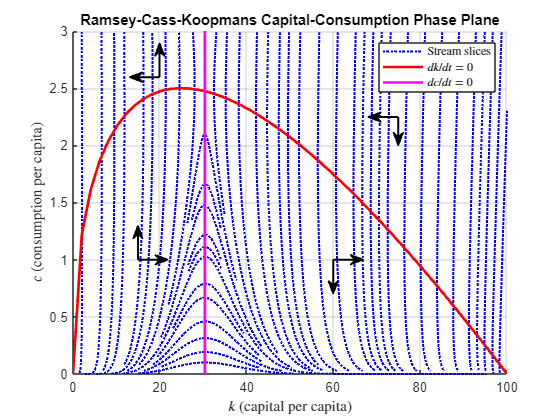

x1 = [15, 15];
y1 = [1.0, 1.3];
x2 = [15, 22];
y2 = [1.0, 1.0];
addDoubleArrow(x1, y1, x2, y2)

## Local function for drawing the annotations.

See also [`ds2nfu`](matlab: edit ds2nfu) for converting data space units to figure units. This function was developed by Michelle Hirsch and is [available on File Exchange](https://uk.mathworks.com/matlabcentral/fileexchange/10656-data-space-to-figure-units-conversion). It makes it easy to add annotations to an existing chart by specifying the coordinates in data space (i.e., axes) units rather than in the figure units required by the [`annotation`](matlab: doc annotation) function.

function addDoubleArrow(x1, y1, x2, y2)

[xFig, yFig] = ds2nfu(x1, y1);
annotation("arrow", xFig, yFig, "LineWidth", 1.5)
[xFig, yFig] = ds2nfu(x2, y2);
annotation("arrow", xFig, yFig, "LineWidth", 1.5)

end % addAnnotation